% TODO: Añadir descripción del código.
% Falta añadir descripción detallada de los pasos seguidos, pero el
% código funciona perfectamente.
clear; clc; clf

syms x
f(x) = sin(x) - cos(x^2) - 1;
df(x) = diff(f(x), x);

f = matlabFunction(f(x));
df = matlabFunction(df(x));

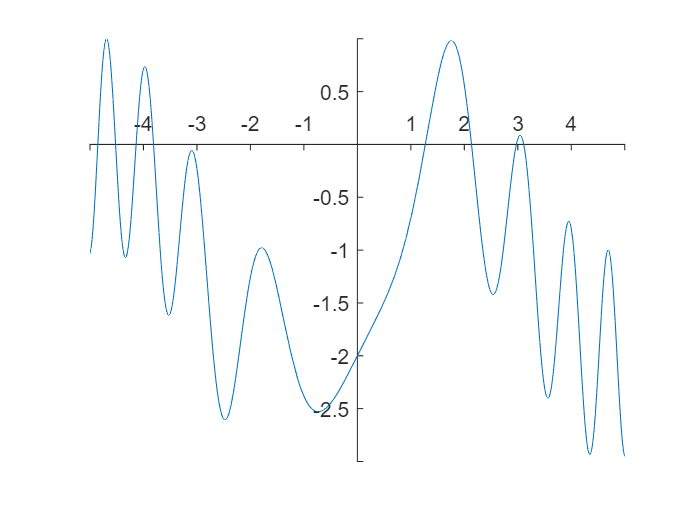

fplot(f)
ax = gca;
ax.XAxisLocation = "origin";
ax.YAxisLocation = "origin";
ax.XTick = ax.XTick;
ax.YTick = ax.YTick;
ax.Box = 0;

x = input("Ingresar x inicial: x = ");
tol = 1e-5;
k = 1;

while abs(f(x)) > tol
    x = x - f(x)./df(x);
    
    k = k + 1;
    if k > 30
        break
    end
end

fprintf("La función tiene un raíz en x = %.4f con %i iteraciones.", ...
    x, k)

La función tiene un raíz en x = 1.2710 con 4 iteraciones.